clc
clear all
close all

Expdata= xlsread('C:\Users\kondiboyina.v\Documents\Vineel\Nano-Indentation Results\Axolotl15cm\Data_analysis\Material_Parameters_VE.xlsx');
m=size(Expdata);

x=1;y=1;z=1;
for i= 1: m(1,1)
    if Expdata(i,1)==3
        Uninjured (x,:) = Expdata(i,:);
        x=x+1;
    elseif Expdata(i,1)==1
        Day27(y,:)=Expdata(i,:);
        y=y+1;
    elseif Expdata(i,1)==2
        Day41(z,:)=Expdata(i,:);
        z=z+1;           
    end
    
end

x=1;y=1;z=1;z0=1;z1=1;z2=1;
for i= 1: m(1,1)
    if Expdata(i,1)==2 & Expdata(i,18)==0
        Day41_0(z0,:)=Expdata(i,:);
        z0=z0+1;        
     elseif Expdata(i,1)==2 & Expdata(i,18)==1
        Day41_1(z1,:)=Expdata(i,:);
        z1=z1+1; 
     elseif Expdata(i,1)==2 & Expdata(i,18)==2
        Day41_2(z2,:)=Expdata(i,:);
        z2=z2+1;        
    end
    
end

**Shear Modulus G1**

G1

Uninj_G= (Uninjured(:,4)/(2*(1+0.25)));
Uninj_G1= Uninj_G.*(1-Uninjured(:,8));
Day27_G= (Day27(:,4)/(2*(1+0.25)));
Day27_G1= Day27_G.*(Day27(:,8));
Day41_G= (Day41(:,4)/(2*(1+0.25)));
Day41_G1= Day41_G.*(Day41(:,8));
Day41_G0_0= (Day41_0(:,4)/(2*(1+0.25)));
Day41_G1_0= Day41_G0_0.*(Day41_0(:,8));
Day41_G0_1= (Day41_1(:,4)/(2*(1+0.25)));
Day41_G1_1= Day41_G0_1.*(Day41_1(:,8));

AvgUninj_G1= mean(Uninj_G1(:,1));
AvgDay27_G1= mean(Day27_G1(:,1));
AvgDay41_G1= mean(Day41_G1(:,1));
Day27linex=[0.75 1.25];
Day27_G1_liney=[AvgDay27_G1 AvgDay27_G1];
Day41linex=[1.75 2.25];
Day41_G1_liney=[AvgDay41_G1 AvgDay41_G1];
Uninjlinex=[2.75 3.25];
Uninj_G1_liney=[AvgUninj_G1 AvgUninj_G1];

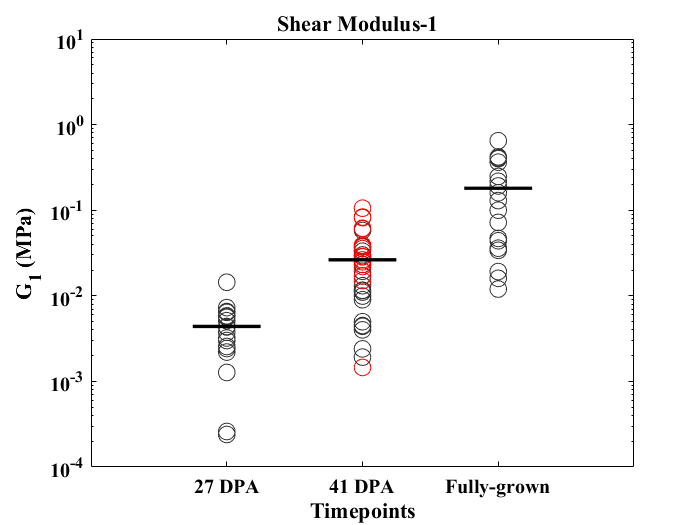

figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
semilogy(Uninjured(:,1),Uninj_G1(:,1),'o','Color',[0.2 0.2 0.2], 'MarkerSize',10)
hold on
semilogy(Day27(:,1),Day27_G1(:,1),'o','Color',[0.2 0.2 0.2], 'MarkerSize',10)
hold on
plot(Day41_0(:,1),Day41_G1_0(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
plot(Day41_1(:,1),Day41_G1_1(:,1),'o','Color',[1 0 0],'MarkerSize',10)
semilogy(Uninjlinex,Uninj_G1_liney,'-k', 'LineWidth',2)
hold on
semilogy(Day27linex,Day27_G1_liney,'-k', 'LineWidth',2)
hold on
semilogy(Day41linex,Day41_G1_liney,'-k', 'LineWidth',2)
hold on
hold off
xlim([0 4])
ylim([10^-4 10^1])
xticks([1 2 3])
xticklabels({'27 DPA','41 DPA','Fully-grown'})

% Create ylabel
ylabel('G_1 (MPa)','FontWeight','bold',...
    'FontName','Times New Roman','FontSize',12);

% Create xlabel
xlabel('Timepoints','FontWeight','bold','FontName','Times New Roman','FontSize',12);

% Create title
title('Shear Modulus-1  ','FontWeight','bold','FontName','Times New Roman','FontSize',16);

box(axes1,'on');
% Set the remaining axes prorerties
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',12,'FontWeight','bold','XColor',[0 0 0],'XTick',[1 2 3],...
    'XTickLabel',{'27 DPA','41 DPA','Fully-grown'},'YColor',[0 0 0],'YMinorTick',...
    'on','YScale','log','ZColor',[0 0 0]);
xl=get(gca,'xlabel');
    pxl = get(xl,'position');
    pxl(2) = 1.05*pxl(2);
    set(xl,'position',pxl)

**Day42 G1 (P-D)**

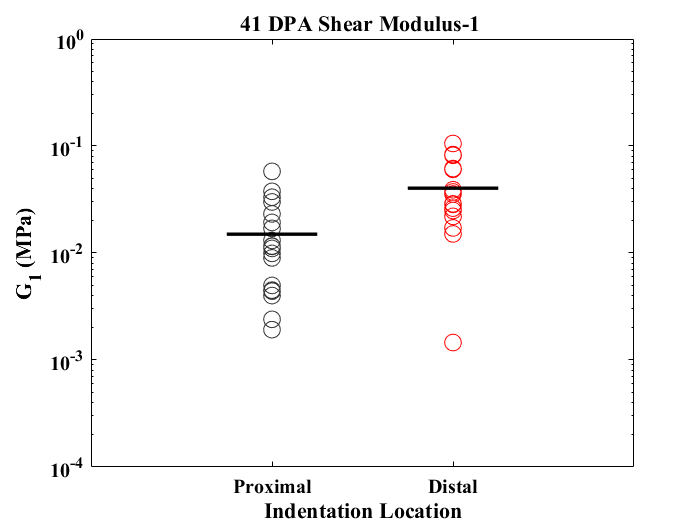

AvgDay41_G1_0= mean(Day41_G1_0(:,1));
AvgDay41_G1_1= mean(Day41_G1_1(:,1));
Day41linex_0=[-0.25 0.25];
Day41_G1_liney_0=[AvgDay41_G1_0 AvgDay41_G1_0];
Day41linex_1=[0.75 1.25];
Day41_G1_liney_1=[AvgDay41_G1_1 AvgDay41_G1_1];

    figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
semilogy(Day41_0(:,18),Day41_G1_0(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
hold on
semilogy(Day41_1(:,18),Day41_G1_1(:,1),'o','Color',[1, 0 0],'MarkerSize',10)
hold on
%semilogy(Day41_2(:,1),Day41_2(:,4),'o','Color',[0, 0, 1],'MarkerSize',10)
%hold on
semilogy(Day41linex_0,Day41_G1_liney_0,'-k', 'LineWidth',2)
semilogy(Day41linex_1,Day41_G1_liney_1,'-k', 'LineWidth',2)
hold on

hold off
xlim([-1 2])
ylim([10^-4 10^0])
xticks([0 1])
xticklabels({'Proximal','Distal'})

% Create ylabel
ylabel('G_1 (MPa)','FontWeight','bold',...
    'FontName','Times New Roman','FontSize',12);

% Create xlabel
xlabel('Indentation Location','FontWeight','bold','FontName','Times New Roman','FontSize',12);

% Create title
title('41 DPA Shear Modulus-1 ','FontWeight','bold','FontName','Times New Roman','FontSize',16);
box(axes1,'on');
% Set the remaining axes prorerties
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',12,'FontWeight','bold','XColor',[0 0 0],'XTick',[0 1],...
    'XTickLabel',{'Proximal','Distal'},'YColor',[0 0 0],'YMinorTick',...
    'on','YScale','log','ZColor',[0 0 0]);
xl=get(gca,'xlabel');
    pxl = get(xl,'position');
    pxl(2) = 1.05*pxl(2);
    set(xl,'position',pxl)

**Day42 G1 (P-D)**

m= size(Day41_G1_0(:,1));n=size(Day41_G1_1(:,1));
Matrix= nan(m(1,1),2);
Matrix(1:m(1,1),1)=Day41_G1_0(:,1);
Matrix(1:n(1,1),2)=Day41_G1_1(:,1);


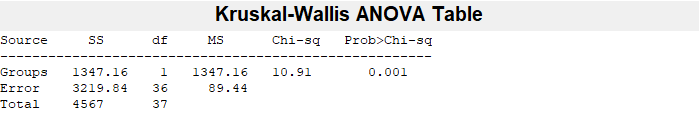

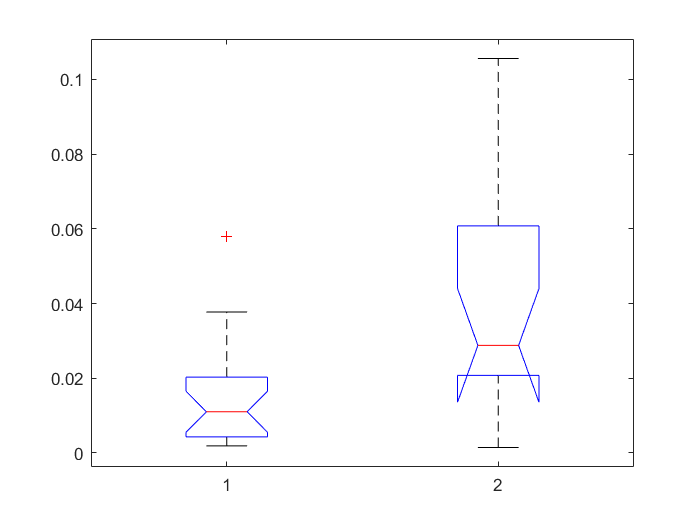

figure
[G1_p,G1_tbl,G1_stats] = kruskalwallis(Matrix);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


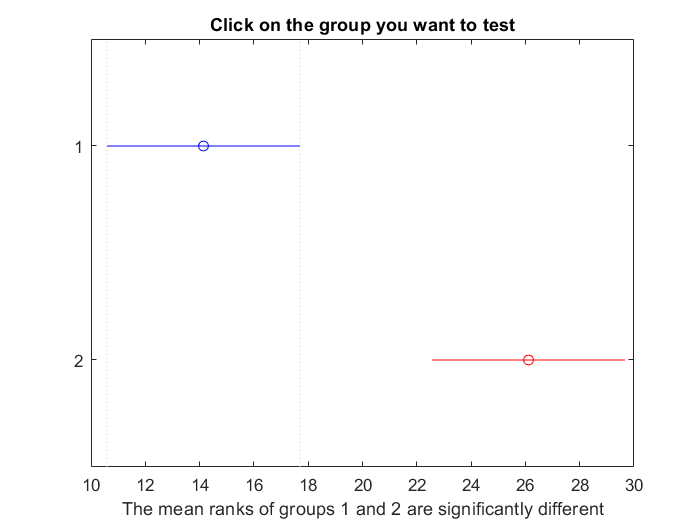

[G1_c,G1_m,G1_h,G1_gnames] = multcompare(G1_stats,'ctype', 'bonferroni'); %pvalues, means and SE, figurehandles, groupnames   

**Shear MOdulus G2**

Uninj_G= (Uninjured(:,4)/(2*(1+0.25)));
Uninj_G2= Uninj_G.*(Uninjured(:,9));
Day27_G= (Day27(:,4)/(2*(1+0.25)));
Day27_G2= Day27_G.*(Day27(:,9));
Day41_G= (Day41(:,4)/(2*(1+0.25)));
Day41_G2= Day41_G.*(Day41(:,9));
Day41_G0_0= (Day41_0(:,4)/(2*(1+0.25)));
Day41_G2_0= Day41_G0_0.*(Day41_0(:,9));
Day41_G0_1= (Day41_1(:,4)/(2*(1+0.25)));
Day41_G2_1= Day41_G0_1.*(Day41_1(:,9));

AvgUninj_G2= mean(Uninj_G2(:,1));
AvgDay27_G2= mean(Day27_G2(:,1));
AvgDay41_G2= mean(Day41_G2(:,1));
Day27linex=[0.75 1.25];
Day27_G2_liney=[AvgDay27_G2 AvgDay27_G2];
Day41linex=[1.75 2.25];
Day41_G2_liney=[AvgDay41_G2 AvgDay41_G2];
Uninjlinex=[2.75 3.25];
Uninj_G2_liney=[AvgUninj_G2 AvgUninj_G2];

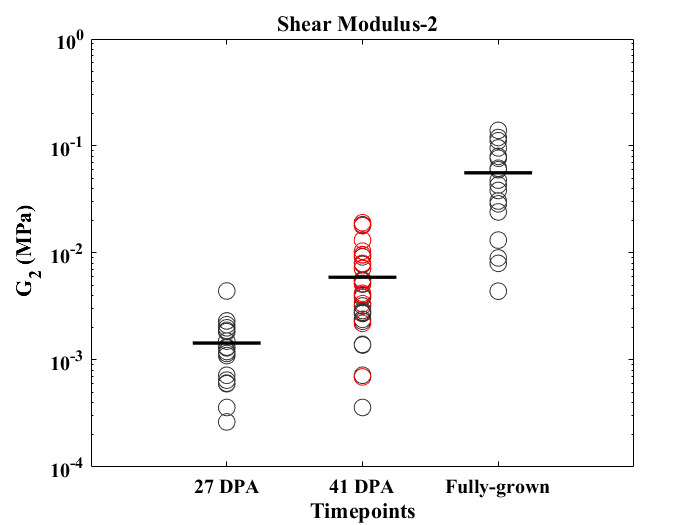

figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
semilogy(Uninjured(:,1),Uninj_G2(:,1),'o','Color',[0.2 0.2 0.2], 'MarkerSize',10)
hold on
semilogy(Day27(:,1),Day27_G2(:,1),'o','Color',[0.2 0.2 0.2], 'MarkerSize',10)
hold on
plot(Day41_0(:,1),Day41_G2_0(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
plot(Day41_1(:,1),Day41_G2_1(:,1),'o','Color',[1 0 0],'MarkerSize',10)
semilogy(Uninjlinex,Uninj_G2_liney,'-k', 'LineWidth',2)
hold on
semilogy(Day27linex,Day27_G2_liney,'-k', 'LineWidth',2)
hold on
semilogy(Day41linex,Day41_G2_liney,'-k', 'LineWidth',2)
hold on
hold off
xlim([0 4])
ylim([10^-4 10^0])
xticks([1 2 3])
xticklabels({'27 DPA','41 DPA','Fully-grown'})

% Create ylabel
ylabel(' G_2 (MPa)','FontWeight','bold',...
    'FontName','Times New Roman','FontSize',12);

% Create xlabel
xlabel('Timepoints','FontWeight','bold','FontName','Times New Roman','FontSize',12);

% Create title
title('Shear Modulus-2  ','FontWeight','bold','FontName','Times New Roman','FontSize',16);

box(axes1,'on');
% Set the remaining axes prorerties
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',12,'FontWeight','bold','XColor',[0 0 0],'XTick',[1 2 3],...
    'XTickLabel',{'27 DPA','41 DPA','Fully-grown'},'YColor',[0 0 0],'YMinorTick',...
    'on','YScale','log','ZColor',[0 0 0]);
xl=get(gca,'xlabel');
    pxl = get(xl,'position');
    pxl(2) = 1.05*pxl(2);
    set(xl,'position',pxl)

**Day42 G2 (P-D)**

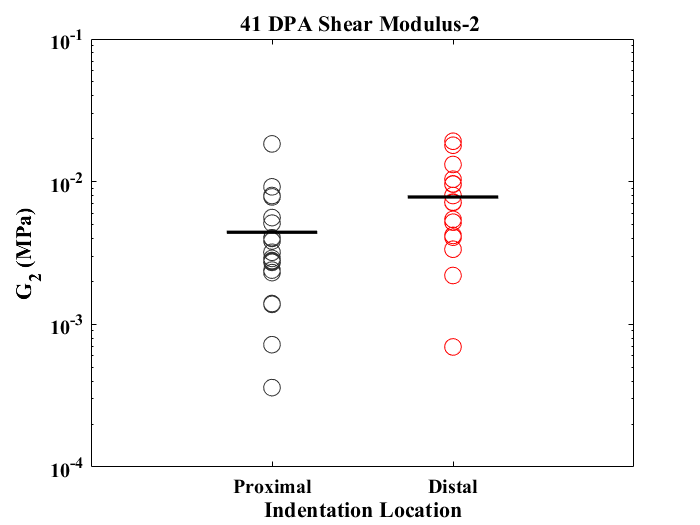

AvgDay41_G2_0= mean(Day41_G2_0(:,1));
AvgDay41_G2_1= mean(Day41_G2_1(:,1));
Day41linex_0=[-0.25 0.25];
Day41_G2_liney_0=[AvgDay41_G2_0 AvgDay41_G2_0];
Day41linex_1=[0.75 1.25];
Day41_G2_liney_1=[AvgDay41_G2_1 AvgDay41_G2_1];

    figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
semilogy(Day41_0(:,18),Day41_G2_0(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
hold on
semilogy(Day41_1(:,18),Day41_G2_1(:,1),'o','Color',[1, 0 0],'MarkerSize',10)
hold on
%semilogy(Day41_2(:,1),Day41_2(:,4),'o','Color',[0, 0, 1],'MarkerSize',10)
%hold on
semilogy(Day41linex_0,Day41_G2_liney_0,'-k', 'LineWidth',2)
semilogy(Day41linex_1,Day41_G2_liney_1,'-k', 'LineWidth',2)
hold on

hold off
xlim([-1 2])
ylim([10^-4 10^-1])
xticks([0 1])
xticklabels({'Proximal','Distal'})

% Create ylabel
ylabel('G_2 (MPa)','FontWeight','bold',...
    'FontName','Times New Roman','FontSize',12);

% Create xlabel
xlabel('Indentation Location','FontWeight','bold','FontName','Times New Roman','FontSize',12);

% Create title
title('41 DPA Shear Modulus-2 ','FontWeight','bold','FontName','Times New Roman','FontSize',16);
box(axes1,'on');
% Set the remaining axes prorerties
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',12,'FontWeight','bold','XColor',[0 0 0],'XTick',[0 1],...
    'XTickLabel',{'Proximal','Distal'},'YColor',[0 0 0],'YMinorTick',...
    'on','YScale','log','ZColor',[0 0 0]);
xl=get(gca,'xlabel');
    pxl = get(xl,'position');
    pxl(2) = 1.05*pxl(2);
    set(xl,'position',pxl)

**Day42 G2 (P-D)**

m= size(Day41_G2_0(:,1));n=size(Day41_G2_1(:,1));
Matrix= nan(m(1,1),2);
Matrix(1:m(1,1),1)=Day41_G2_0(:,1);
Matrix(1:n(1,1),2)=Day41_G2_1(:,1);


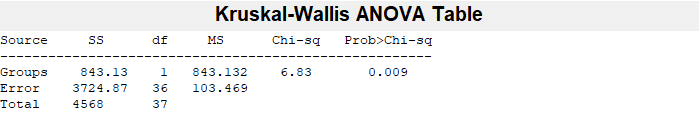

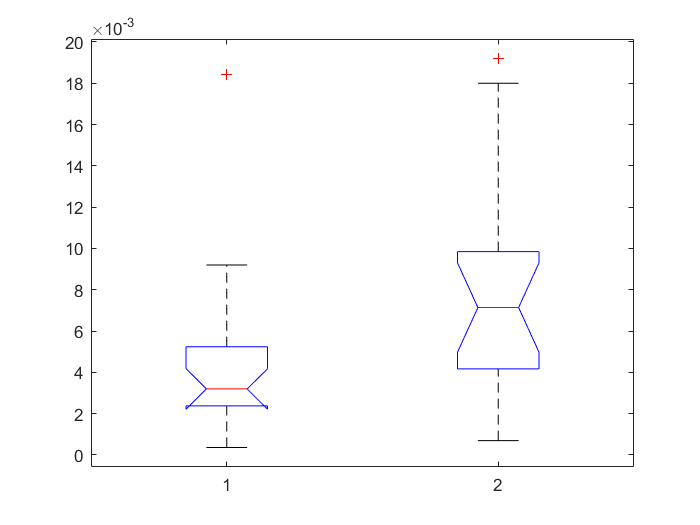

figure
[G2_p,G2_tbl,G2_stats] = kruskalwallis(Matrix);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


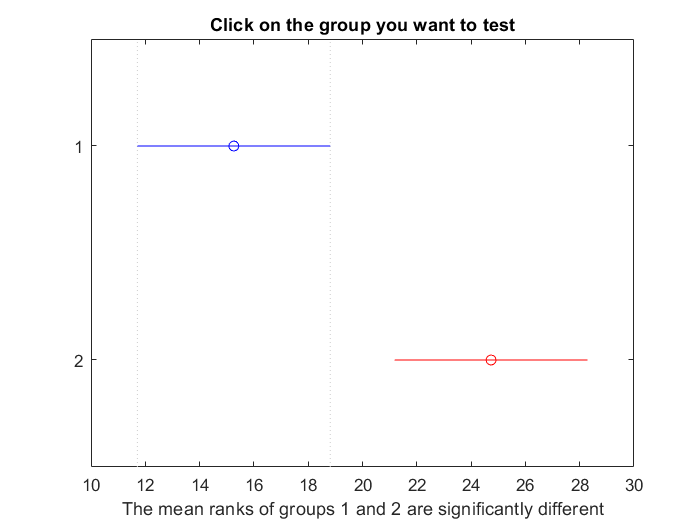

[G2_c,G2_m,G2_h,G2_gnames] = multcompare(G2_stats,'ctype', 'bonferroni'); %pvalues, means and SE, figurehandles, groupnames   

## **Ginf**

% Uninj_Ginf= Uninj_G-Uninj_G1-Uninj_G2;
% Day27_Ginf= Day27_G-Day27_G1-Day27_G2;
% Day41_Ginf= Day41_G-Day41_G1-Day41_G2;
% Day41_Ginf0= Day41_G0_0-Day41_G1_0-Day41_G2_0;
% Day41_Ginf1= Day41_G0_1-Day41_G1_1-Day41_G2_1;

% figure1=figure;
% axes1 = axes('Parent',figure1);
% hold(axes1,'on');
% semilogy(Uninjured(:,1),Uninj_Ginf(:,1),'o','Color',[0.2 0.2 0.2], 'MarkerSize',10)
% hold on
% semilogy(Day27(:,1),Day27_Ginf(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
% hold on
% semilogy(Day41_0(:,1),Day41_Ginf0(:,1),'o','Color',[0.2 0.2 0.2],'MarkerSize',10)
% hold on
% semilogy(Day41_1(:,1),Day41_Ginf1(:,1),'o','Color',[1, 0 0],'MarkerSize',10)
% % hold on
% % semilogy(Uninjlinex,Uninj_G_liney,'-k', 'LineWidth',2)
% % hold on
% % semilogy(Day27linex,Day27_G_liney,'-k', 'LineWidth',2)
% % hold on
% % semilogy(Day41linex,Day41_G_liney,'-k', 'LineWidth',2)
% % hold on
% hold off
% xlim([0 4])
% ylim([10^-5.5 10^2])
% xticks([1 2 3])
% xticklabels({'27 DPA','41 DPA','Fully-grown'})
% 
% % Create ylabel
% ylabel('Equilibrium Shear Modulus G_e_q (MPa)','FontWeight','bold',...
%     'FontName','Times New Roman','FontSize',12);
% 
% % Create xlabel
% xlabel('Timepoints','FontWeight','bold','FontName','Times New Roman','FontSize',12);
% 
% % Create title
% title('Equilibrium Shear Modulus of  ','FontWeight','bold','FontName','Times New Roman','FontSize',16);
% 
% box(axes1,'on');
% % Set the remaining axes prorerties
% set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
%     'FontSize',12,'FontWeight','bold','XColor',[0 0 0],'XTick',[1 2 3],...
%     'XTickLabel',{'27 DPA','41 DPA','Fully-grown'},'YColor',[0 0 0],'YMinorTick',...
%     'on','YScale','log','ZColor',[0 0 0]);
% xl=get(gca,'xlabel');
%     pxl = get(xl,'position');
%     pxl(2) = 1.05*pxl(2);
%     set(xl,'position',pxl)
%     